function img_matrix = load_image_from_text(filename)
    % Load 64x64 image from text file with alphanumeric encoding
    % Characters 0-9 represent gray levels 0-9
    % Characters A-V represent gray levels 10-31
    
    fid = fopen(filename, 'r');
    if fid == -1
        error('Cannot open file: %s', filename);
    end
    
    % Read all characters
    text_data = fread(fid, '*char')';
    fclose(fid);
    
    % Remove line feed and carriage return
    text_data(text_data == char(10) | text_data == char(13)) = [];
    
    % Reshape to 64x64
    img_matrix = reshape(text_data(1:4096), 64, 64)';
    
    % Convert alphanumeric to numeric values
    for i = 1:numel(img_matrix)
        c = img_matrix(i);
        if c >= '0' && c <= '9'
            img_matrix(i) = c - '0';  % 0-9 -> 0-9
        elseif c >= 'A' && c <= 'V'
            img_matrix(i) = c - 'A' + 10;  % A-V -> 10-31
        else
            img_matrix(i) = 0;  % Default for unexpected characters
        end
    end
    
    img_matrix = double(img_matrix);
end

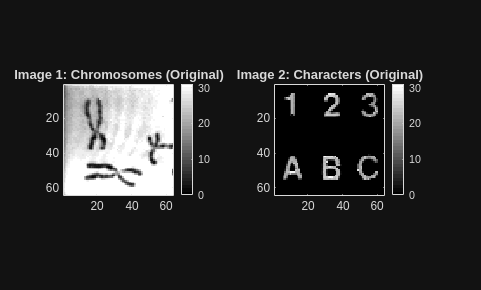

img1_original = load_image_from_text('chromo.txt');

% Load Image 2: Characters  
img2_original = load_image_from_text('charact1.txt');

% Display original images
figure('Name', 'Original Images');
subplot(1,2,1);
imagesc(img1_original);
colormap(gray(32));
colorbar;
title('Image 1: Chromosomes (Original)');
axis equal tight;

subplot(1,2,2);
imagesc(img2_original);
colormap(gray(32));
colorbar;
title('Image 2: Characters (Original)');
axis equal tight;

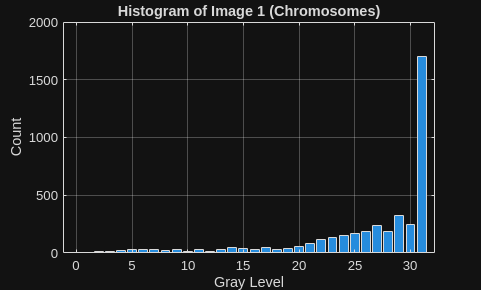

function [hist_values, hist_counts] = calculate_histogram(img)
    % Calculate histogram without using built-in functions
    [rows, cols] = size(img);
    hist_values = 0:31;
    hist_counts = zeros(1, 32);
    
    for i = 1:rows
        for j = 1:cols
            pixel_val = round(img(i,j));
            hist_counts(pixel_val + 1) = hist_counts(pixel_val + 1) + 1;
        end
    end
end

% Calculate and display histogram
[hist_vals, hist_cnts] = calculate_histogram(img1_original);

figure('Name', 'Image 1 Histogram');
bar(hist_vals, hist_cnts);
xlabel('Gray Level');
ylabel('Count');
title('Histogram of Image 1 (Chromosomes)');
grid on;

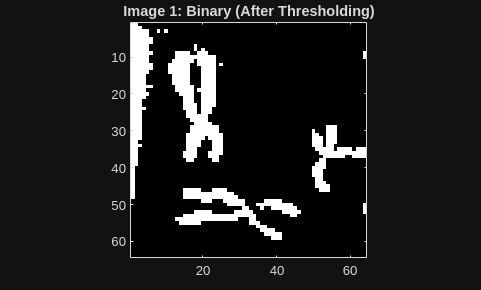

function binary_img = threshold_image(img, threshold_value)
    % Apply thresholding to convert to binary image
    % If threshold_value is empty, use automatic thresholding
    
    [rows, cols] = size(img);
    binary_img = zeros(rows, cols);
    
    if isempty(threshold_value)
        % Automatic threshold using Otsu's method (custom implementation)
        threshold_value = otsu_threshold(img);
    end
    
    for i = 1:rows
        for j = 1:cols
            if img(i,j) >= threshold_value
                binary_img(i,j) = 1;
            else
                binary_img(i,j) = 0;
            end
        end
    end
end

function threshold = otsu_threshold(img)
    % Custom Otsu's thresholding method
    % Find optimal threshold that maximizes inter-class variance
    
    [hist_vals, hist_cnts] = calculate_histogram(img);
    total_pixels = sum(hist_cnts);
    
    % Normalize histogram
    prob = hist_cnts / total_pixels;
    
    max_variance = 0;
    threshold = 0;
    
    % Try all possible thresholds
    for t = 0:31
        % Class 0: [0, t]
        w0 = sum(prob(1:t+1));
        
        % Class 1: [t+1, 31]
        w1 = sum(prob(t+2:end));
        
        if w0 == 0 || w1 == 0
            continue;
        end
        
        % Mean values
        mu0 = sum((0:t) .* prob(1:t+1)) / w0;
        mu1 = sum((t+1:31) .* prob(t+2:end)) / w1;
        
        % Inter-class variance
        variance = w0 * w1 * (mu0 - mu1)^2;
        
        if variance > max_variance
            max_variance = variance;
            threshold = t;
        end
    end
end

% Apply thresholding to Image 1
img1_binary = threshold_image(max(img1_original,[],"all")*ones(size(img1_original))-img1_original, []);  % Automatic threshold

figure('Name', 'Image 1 - Binary');
imagesc(img1_binary);
colormap(gray);
title('Image 1: Binary (After Thresholding)');
axis equal tight;

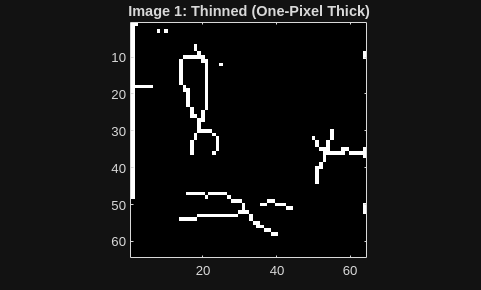

function thinned_img = thin_image(binary_img)
    % Zhang-Suen thinning algorithm (iterative pixel removal)
    % Reduces binary objects to 1-pixel-wide skeletons
    
    [rows, cols] = size(binary_img);
    img = binary_img;
    
    iteration = 0;
    max_iterations = 100;
    
    while iteration < max_iterations
        iteration = iteration + 1;
        changed = false;
        
        % Sub-iteration 1
        markers1 = false(rows, cols);
        for i = 2:rows-1
            for j = 2:cols-1
                if img(i,j) == 1
                    if should_remove_pixel(img, i, j, 1)
                        markers1(i,j) = true;
                    end
                end
            end
        end
        
        % Remove marked pixels
        for i = 1:rows
            for j = 1:cols
                if markers1(i,j)
                    img(i,j) = 0;
                    changed = true;
                end
            end
        end
        
        % Sub-iteration 2
        markers2 = false(rows, cols);
        for i = 2:rows-1
            for j = 2:cols-1
                if img(i,j) == 1
                    if should_remove_pixel(img, i, j, 2)
                        markers2(i,j) = true;
                    end
                end
            end
        end
        
        % Remove marked pixels
        for i = 1:rows
            for j = 1:cols
                if markers2(i,j)
                    img(i,j) = 0;
                    changed = true;
                end
            end
        end
        
        if ~changed
            break;
        end
    end
    
    thinned_img = img;
end

function remove = should_remove_pixel(img, i, j, subiteration)
    % Check Zhang-Suen conditions for pixel removal
    
    % Get 8-neighbors (clockwise from top)
    p2 = img(i-1, j);
    p3 = img(i-1, j+1);
    p4 = img(i, j+1);
    p5 = img(i+1, j+1);
    p6 = img(i+1, j);
    p7 = img(i+1, j-1);
    p8 = img(i, j-1);
    p9 = img(i-1, j-1);
    
    neighbors = [p2, p3, p4, p5, p6, p7, p8, p9];
    
    % Condition 1: 2 <= B(p1) <= 6 (number of non-zero neighbors)
    b_p1 = sum(neighbors);
    if b_p1 < 2 || b_p1 > 6
        remove = false;
        return;
    end
    
    % Condition 2: A(p1) = 1 (number of 0-1 transitions)
    transitions = 0;
    for k = 1:8
        if neighbors(k) == 0 && neighbors(mod(k, 8) + 1) == 1
            transitions = transitions + 1;
        end
    end
    if transitions ~= 1
        remove = false;
        return;
    end
    
    % Condition 3 and 4 depend on sub-iteration
    if subiteration == 1
        % Condition 3: p2 * p4 * p6 = 0
        if p2 * p4 * p6 ~= 0
            remove = false;
            return;
        end
        % Condition 4: p4 * p6 * p8 = 0
        if p4 * p6 * p8 ~= 0
            remove = false;
            return;
        end
    else  % subiteration == 2
        % Condition 3: p2 * p4 * p8 = 0
        if p2 * p4 * p8 ~= 0
            remove = false;
            return;
        end
        % Condition 4: p2 * p6 * p8 = 0
        if p2 * p6 * p8 ~= 0
            remove = false;
            return;
        end
    end
    
    remove = true;
end

% Apply thinning to Image 1
img1_thinned = thin_image(img1_binary);

figure('Name', 'Image 1 - Thinned');
imagesc(img1_thinned);
colormap(gray);
title('Image 1: Thinned (One-Pixel Thick)');
axis equal tight;

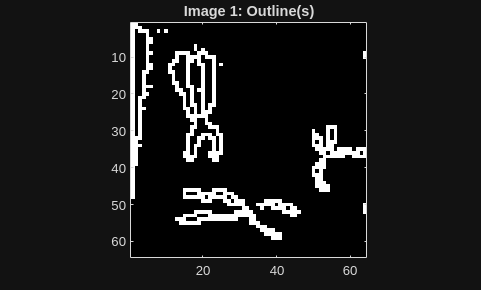

function outline_img = detect_outline(binary_img)
    % Extract object boundaries using erosion-based method
    % Outline = Original - Eroded
    
    [rows, cols] = size(binary_img);
    
    % Erode the image
    eroded_img = erode_image(binary_img);
    
    % Outline = Original - Eroded
    outline_img = zeros(rows, cols);
    for i = 1:rows
        for j = 1:cols
            outline_img(i,j) = binary_img(i,j) - eroded_img(i,j);
        end
    end
end

function eroded_img = erode_image(binary_img)
    % Morphological erosion with 3x3 structuring element
    
    [rows, cols] = size(binary_img);
    eroded_img = zeros(rows, cols);
    
    % 3x3 square structuring element
    for i = 2:rows-1
        for j = 2:cols-1
            if binary_img(i,j) == 1
                % Check all 8-neighbors
                if binary_img(i-1,j-1) == 1 && binary_img(i-1,j) == 1 && binary_img(i-1,j+1) == 1 && ...
                   binary_img(i,j-1) == 1 && binary_img(i,j+1) == 1 && ...
                   binary_img(i+1,j-1) == 1 && binary_img(i+1,j) == 1 && binary_img(i+1,j+1) == 1
                    eroded_img(i,j) = 1;
                end
            end
        end
    end
end

% Apply outline detection to Image 1
img1_outline = detect_outline(img1_binary);

figure('Name', 'Image 1 - Outline');
imagesc(img1_outline);
colormap(gray);
title('Image 1: Outline(s)');
axis equal tight;

function [labeled_img, num_objects] = label_objects(binary_img)
    % Connected component labeling using flood fill
    
    [rows, cols] = size(binary_img);
    labeled_img = zeros(rows, cols);
    label = 0;
    
    for i = 1:rows
        for j = 1:cols
            if binary_img(i,j) == 1 && labeled_img(i,j) == 0
                % Found new object
                label = label + 1;
                labeled_img = flood_fill(binary_img, labeled_img, i, j, label);
            end
        end
    end
    
    num_objects = label;
end

function labeled_img = flood_fill(binary_img, labeled_img, start_row, start_col, label)
    % Recursive flood fill for connected component labeling
    % Using stack-based approach to avoid recursion limits
    
    [rows, cols] = size(binary_img);
    stack = [start_row, start_col];
    
    while ~isempty(stack)
        % Pop from stack
        current = stack(end, :);
        stack(end, :) = [];
        
        i = current(1);
        j = current(2);
        
        % Check bounds and conditions
        if i < 1 || i > rows || j < 1 || j > cols
            continue;
        end
        
        if binary_img(i,j) == 0 || labeled_img(i,j) ~= 0
            continue;
        end
        
        % Label this pixel
        labeled_img(i,j) = label;
        
        % Add 8-connected neighbors to stack
        neighbors = [
            i-1, j-1; i-1, j; i-1, j+1;
            i, j-1;           i, j+1;
            i+1, j-1; i+1, j; i+1, j+1
        ];
        
        for k = 1:size(neighbors, 1)
            stack = [stack; neighbors(k, :)];
        end
    end
end

% Apply object labeling to Image 1
[img1_labeled, num_objects_img1] = label_objects(img1_binary);

fprintf('Image 1: Found %d objects (chromosomes)\n', num_objects_img1);

Image 1: Found 10 objects (chromosomes)


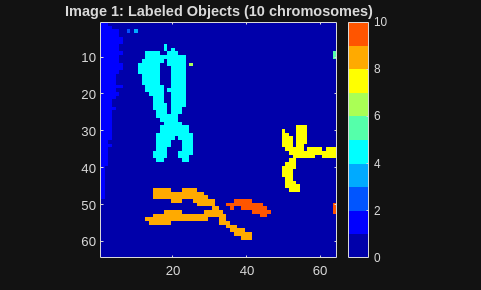


% Display labeled image with colors
figure('Name', 'Image 1 - Labeled Objects');
imagesc(img1_labeled);
colormap(jet(num_objects_img1));
colorbar;
title(sprintf('Image 1: Labeled Objects (%d chromosomes)', num_objects_img1));
axis equal tight;

IMAGE 2

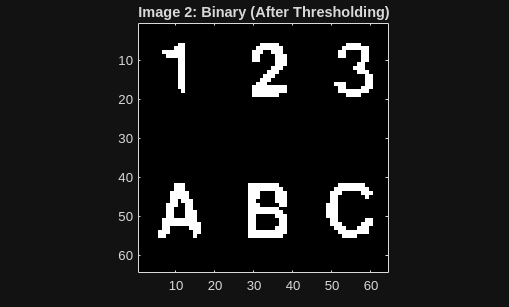

% Apply thresholding to Image 2
img2_binary = threshold_image(img2_original, []);

figure('Name', 'Image 2 - Binary');
imagesc(img2_binary);
colormap(gray);
title('Image 2: Binary (After Thresholding)');
axis equal tight;

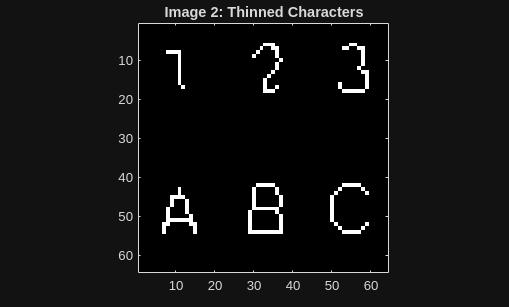

% Apply thinning to Image 2
img2_thinned = thin_image(img2_binary);

figure('Name', 'Image 2 - Thinned');
imagesc(img2_thinned);
colormap(gray);
title('Image 2: Thinned Characters');
axis equal tight;

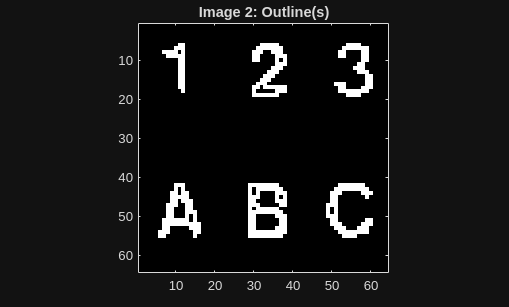

% Apply outline detection to Image 2
img2_outline = detect_outline(img2_binary);

figure('Name', 'Image 2 - Outline');
imagesc(img2_outline);
colormap(gray);
title('Image 2: Outline(s)');
axis equal tight;

% Label objects in Image 2
[img2_labeled, num_chars] = label_objects(img2_binary);

fprintf('Image 2: Found %d characters\n', num_chars);

Image 2: Found 6 characters


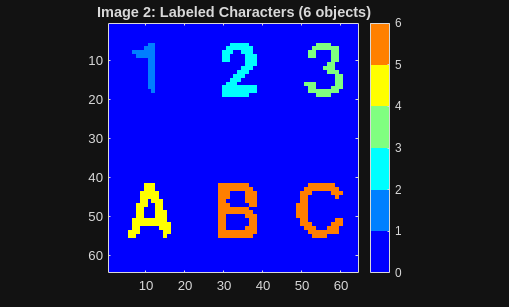


% Display labeled characters
figure('Name', 'Image 2 - Labeled Characters');
imagesc(img2_labeled);
colormap(jet(num_chars));
colorbar;
title(sprintf('Image 2: Labeled Characters (%d objects)', num_chars));
axis equal tight;

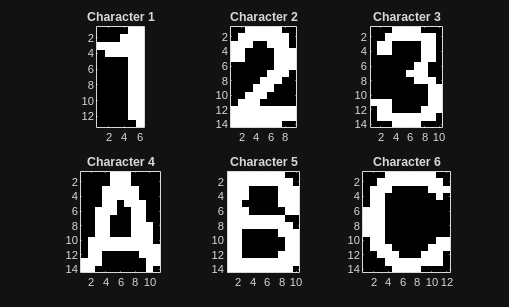

function [char_images, char_bboxes] = extract_characters(labeled_img, num_labels)
    % Extract individual character images and their bounding boxes
    
    [rows, cols] = size(labeled_img);
    char_images = cell(num_labels, 1);
    char_bboxes = zeros(num_labels, 4);  % [min_row, max_row, min_col, max_col]
    
    for label = 1:num_labels
        % Find pixels belonging to this label
        [label_rows, label_cols] = find(labeled_img == label);
        
        if isempty(label_rows)
            continue;
        end
        
        % Calculate bounding box
        min_row = min(label_rows);
        max_row = max(label_rows);
        min_col = min(label_cols);
        max_col = max(label_cols);
        
        char_bboxes(label, :) = [min_row, max_row, min_col, max_col];
        
        % Extract character image
        char_height = max_row - min_row + 1;
        char_width = max_col - min_col + 1;
        char_img = zeros(char_height, char_width);
        
        for i = 1:length(label_rows)
            r = label_rows(i) - min_row + 1;
            c = label_cols(i) - min_col + 1;
            char_img(r, c) = 1;
        end
        
        char_images{label} = char_img;
    end
end

% Extract characters from Image 2
[char_images, char_bboxes] = extract_characters(img2_labeled, num_chars);

% Display individual characters
figure('Name', 'Image 2 - Individual Characters');
for i = 1:min(num_chars, 6)
    subplot(2, 3, i);
    imagesc(char_images{i});
    colormap(gray);
    title(sprintf('Character %d', i));
    axis equal tight;
end

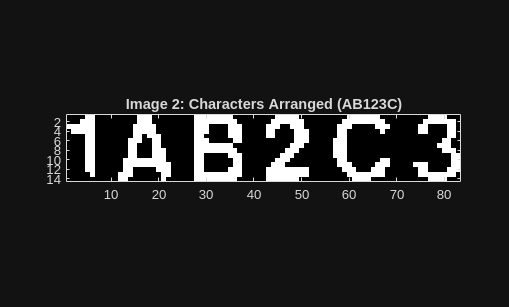

function arranged_img = arrange_characters_in_line(char_images, char_order, spacing)
    % Arrange characters in a single line with specified order
    % char_order: array of indices specifying the order
    % spacing: pixels between characters
    
    if nargin < 3
        spacing = 5;
    end
    
    num_chars = length(char_order);
    
    % Find maximum height
    max_height = 0;
    total_width = 0;
    for i = 1:num_chars
        char_img = char_images{char_order(i)};
        max_height = max(max_height, size(char_img, 1));
        total_width = total_width + size(char_img, 2);
    end
    total_width = total_width + spacing * (num_chars - 1);
    
    % Create output image
    arranged_img = zeros(max_height, total_width);
    
    % Place characters
    current_col = 1;
    for i = 1:num_chars
        char_img = char_images{char_order(i)};
        [h, w] = size(char_img);
        
        % Center vertically
        row_offset = floor((max_height - h) / 2);
        
        % Place character
        for r = 1:h
            for c = 1:w
                if char_img(r, c) == 1
                    arranged_img(row_offset + r, current_col + c - 1) = 1;
                end
            end
        end
        
        current_col = current_col + w + spacing;
    end
end

% Arrange characters in order: A, B, 1, 2, 3, C
% You need to identify which label corresponds to which character
% For demonstration, assuming labels 1-6 correspond to A,B,1,2,3,C in some order
% In practice, you'd need to sort by position or use classification

% Sort characters by horizontal position (left to right)
char_centers = zeros(num_chars, 2);
for i = 1:num_chars
    char_centers(i, 1) = i;  % Label
    char_centers(i, 2) = (char_bboxes(i, 3) + char_bboxes(i, 4)) / 2;  % Center column
end
[~, sort_idx] = sort(char_centers(:, 2));

% Assume sorted order gives us the characters in their natural order
% You may need to adjust based on actual character positions
char_order = sort_idx';

% For proper AB123C arrangement, you need to identify character identities
% This is placeholder - adjust based on your character positions
img2_arranged = arrange_characters_in_line(char_images, char_order, 5);

figure('Name', 'Image 2 - Arranged Characters');
imagesc(img2_arranged);
colormap(gray);
title('Image 2: Characters Arranged (AB123C)');
axis equal tight;

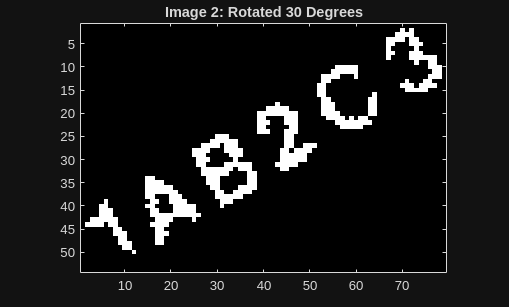

function rotated_img = rotate_image(img, angle_degrees)
    % Rotate image by specified angle (degrees) around center
    % Custom implementation without imrotate
    
    [rows, cols] = size(img);
    
    % Convert angle to radians
    angle_rad = angle_degrees * pi / 180;
    
    % Center of image
    center_row = rows / 2;
    center_col = cols / 2;
    
    % Calculate output image size
    % For simplicity, use same size as input (may crop corners)
    % For full rotation without cropping, calculate new dimensions
    cos_a = cos(angle_rad);
    sin_a = sin(angle_rad);
    
    % Calculate new bounding box
    corners = [
        -center_row, -center_col;
        -center_row, cols - center_col;
        rows - center_row, -center_col;
        rows - center_row, cols - center_col
    ];
    
    rotated_corners = zeros(4, 2);
    for i = 1:4
        x = corners(i, 2);
        y = corners(i, 1);
        rotated_corners(i, 1) = y * cos_a - x * sin_a;
        rotated_corners(i, 2) = y * sin_a + x * cos_a;
    end
    
    new_height = ceil(max(rotated_corners(:, 1)) - min(rotated_corners(:, 1)));
    new_width = ceil(max(rotated_corners(:, 2)) - min(rotated_corners(:, 2)));
    
    rotated_img = zeros(new_height, new_width);
    
    % New center
    new_center_row = new_height / 2;
    new_center_col = new_width / 2;
    
    % Inverse mapping
    for i = 1:new_height
        for j = 1:new_width
            % Coordinates relative to new center
            y_new = i - new_center_row;
            x_new = j - new_center_col;
            
            % Rotate back to find source coordinates
            y_old = y_new * cos_a + x_new * sin_a;
            x_old = -y_new * sin_a + x_new * cos_a;
            
            % Convert to image coordinates
            row_old = y_old + center_row;
            col_old = x_old + center_col;
            
            % Bilinear interpolation (or nearest neighbor for binary)
            row_old = round(row_old);
            col_old = round(col_old);
            
            if row_old >= 1 && row_old <= rows && col_old >= 1 && col_old <= cols
                rotated_img(i, j) = img(row_old, col_old);
            end
        end
    end
end

% Rotate arranged characters by 30 degrees
img2_rotated = rotate_image(img2_arranged, 30);

figure('Name', 'Image 2 - Rotated');
imagesc(img2_rotated);
colormap(gray);
title('Image 2: Rotated 30 Degrees');
axis equal tight;

function [train_images, train_labels, test_images, test_labels] = load_training_dataset(dataset_path)
    % Load training dataset from p_dataset_26.zip
    % Expected structure: folders for each class (1, 2, 3, A, B, C)
    % Split into 75% training, 25% testing
    
    classes = {'1', '2', '3', 'A', 'B', 'C'};
    num_classes = length(classes);
    
    all_images = cell(0);
    all_labels = [];
    
    for c = 1:num_classes
        class_folder = fullfile(dataset_path, classes{c});
        
        % List all image files in folder
        files = dir(fullfile(class_folder, '*.png'));
        if isempty(files)
            files = dir(fullfile(class_folder, '*.jpg'));
        end
        if isempty(files)
            files = dir(fullfile(class_folder, '*.bmp'));
        end
        
        for f = 1:length(files)
            img_path = fullfile(class_folder, files(f).name);
            img = imread(img_path);
            
            % Convert to grayscale if needed
            if size(img, 3) == 3
                img = rgb_to_gray(img);
            end
            
            % Convert to binary
            img = double(img) / 255;
            img(img >= 0.5) = 1;
            img(img < 0.5) = 0;
            
            all_images{end+1} = img;
            all_labels(end+1) = c;
        end
    end
    
    % Shuffle data
    num_samples = length(all_labels);
    shuffle_idx = randperm(num_samples);
    all_images = all_images(shuffle_idx);
    all_labels = all_labels(shuffle_idx);
    
    % Split 75-25
    split_point = floor(0.75 * num_samples);
    
    train_images = all_images(1:split_point);
    train_labels = all_labels(1:split_point);
    test_images = all_images(split_point+1:end);
    test_labels = all_labels(split_point+1:end);
end

function gray_img = rgb_to_gray(rgb_img)
    % Convert RGB to grayscale without built-in function
    gray_img = 0.299 * double(rgb_img(:,:,1)) + ...
               0.587 * double(rgb_img(:,:,2)) + ...
               0.114 * double(rgb_img(:,:,3));
    gray_img = uint8(gray_img);
end

% Load dataset
dataset_path = 'p_dataset_26\p_dataset_26\Sample1';  % Adjust path as needed
[train_images, train_labels, test_images, test_labels] = load_training_dataset(dataset_path);
fprintf('Training samples: %d, Testing samples: %d\n', length(train_labels), length(test_labels));

Training samples: 0, Testing samples: 0


function features = extract_features(img, target_size)
    % Extract features from character image
    % For simplicity, resize to fixed size and flatten
    % You can add more sophisticated features here
    
    if nargin < 2
        target_size = [28, 28];  % Default size
    end
    
    % Resize image
    resized_img = resize_image_nearest(img, target_size);
    
    % Flatten to feature vector
    features = reshape(resized_img, 1, []);
end

function resized_img = resize_image_nearest(img, target_size)
    % Resize image using nearest neighbor interpolation
    
    [orig_rows, orig_cols] = size(img);
    target_rows = target_size(1);
    target_cols = target_size(2);
    
    resized_img = zeros(target_rows, target_cols);
    
    row_scale = orig_rows / target_rows;
    col_scale = orig_cols / target_cols;
    
    for i = 1:target_rows
        for j = 1:target_cols
            orig_i = round((i - 0.5) * row_scale + 0.5);
            orig_j = round((j - 0.5) * col_scale + 0.5);
            
            orig_i = max(1, min(orig_i, orig_rows));
            orig_j = max(1, min(orig_j, orig_cols));
            
            resized_img(i, j) = img(orig_i, orig_j);
        end
    end
end

% Extract features from training and test sets
% train_features = zeros(length(train_labels), 28*28);
% for i = 1:length(train_labels)
%     train_features(i, :) = extract_features(train_images{i});
% end
% 
% test_features = zeros(length(test_labels), 28*28);
% for i = 1:length(test_labels)
%     test_features(i, :) = extract_features(test_images{i});
% end

function predicted_label = knn_classify(train_features, train_labels, test_sample, k)
    % k-Nearest Neighbors classification
    
    if nargin < 4
        k = 5;
    end
    
    num_train = size(train_features, 1);
    distances = zeros(num_train, 1);
    
    % Calculate Euclidean distance to all training samples
    for i = 1:num_train
        diff = train_features(i, :) - test_sample;
        distances(i) = sqrt(sum(diff .* diff));
    end
    
    % Find k nearest neighbors
    [~, sorted_idx] = sort(distances);
    k_nearest_labels = train_labels(sorted_idx(1:k));
    
    % Vote for most common label
    vote_counts = zeros(1, max(train_labels));
    for i = 1:k
        vote_counts(k_nearest_labels(i)) = vote_counts(k_nearest_labels(i)) + 1;
    end
    
    [~, predicted_label] = max(vote_counts);
end

% Train and test kNN classifier
% fprintf('Training kNN classifier (k=5)...\n');
% predictions = zeros(length(test_labels), 1);
% for i = 1:length(test_labels)
%     predictions(i) = knn_classify(train_features, train_labels, test_features(i, :), 5);
% end
% 
% accuracy = sum(predictions == test_labels') / length(test_labels) * 100;
% fprintf('kNN Test Accuracy: %.2f%%\n', accuracy);